# RVC 1, Ch 3.1

clear 
close all
clc
clear livescript

## Lec 04.1 (Ch 3.1) `Paths and Trajectories`

`Paths and trajectories are critical in robots. `

`Generating them control how a robot will move. General goals include smoothness, energy efficiency, safety, and accuracy. `

`Let's start by looking at a path given a starting and goal pose. `

`The path does not control how much time it takes to reach the goal, that is only done with trajectories. `

`The starting pose will be the trivial transformation. A 4x4 homogeneous transformation matrix corresponding to zero rotation and translation:`

T0 = eye(4,4)

Let's visualize the transformation matrices using the toolbox function trplot():

trplot(T0, 'view', [85,15], 'rgb')

`The final pose comprises of an offset of (1,2,3) and an rpy rotation of (0.6,0.8,1.4) radians:`

T1 = transl(1,2,3)*rpy2tr(0.6,0.8,1.4)

Let's visualize the transformation matrices using the toolbox function trplot():

trplot(T1, 'view', [85,15], 'rgb')

### Animation:

There is a fun way to animate the transformation from the starting pose to the ending pose using tranimate(). (Note, run directly in the command window).

tranimate(T0, T1, 'rgb')

## Lec 04.2 (Ch 3.1) Polynomial (smooth) trajectories

`Let's start generating a simple 1D smooth trajectory to introdcuce concepts. `

`We will need a starting and ending pose. We will start `at position 0 and end at position 1. You may want to create a smooth trajectory between these two points over 50 time steps. To do so, use the tpoly() method: 

tpoly(0, 1, 50)

Analyze the plot above in its three forms: position, velocity, and acceleration. 

- Does the trajectory smoothly vary from the set initial position to the target position?

- What is the initial and final velocities?

- How does the trajectory accelerate and decelerate to meet its position and velocity targets in a smooth manner?

We can easily change the target position to -1 to create a new trajectory:

tpoly(0, -1, 50)

The trajectory can be saved by providing an output variable:

s = tpoly(0, 1, 50)

But there is also the possibility to store not only the positino but also the velocity and accelerations:

[s, sd, sdd] = tpoly(0, 1, 50)

### Controlling Initial and Final Velocities

There are times when setting initial and final velocities is desirable. To do so, we can add the starting and ending velocities in tpoly immediately after the timesteps. If you want to start with a velocity of 0.5 units/s and end at 0 units/s do:

tpoly(0, 1, 50, 0.5, 0)

## Lec 04.3 (Ch 3.1) 1D trapezoidal trajectories

Trapezoidal trajectories look to make a more efficient use of a motor's power by maintaining a lower than peak velocity for an extended period of time of the trajectory.  This diminishes the power requirements a motor might need. 

Trapezoidal position trajectories are known as "linear segment with parabolic blend" (lspb). We can instanitate this trajectory using lspb with the same conditions as tpoly:

lspb(0, 1, 50)

We can, as before, save position, velocity, and acceleration profiles:

[s, sd, sdd] = lspb(0, 1, 50)

### Controlling the Trapezoidal Velocity

As with tpoly, we can manipulate velocities. However, rather than controling the starting and ending velocities, here we set the max value that the velocity should reach in the trapezoidal segment. If we set that velocity to 0.025 units/s:

lspb(0, 1, 50, 0.025)

Notice, how the 2nd plot reaches the specificied velocity. However, such velocity profile leads to discontinuities in the acceleration. 

Notice, you can increase the trapezoidal velocity. If we set it to 0.035 units/s:

lspb(0, 1, 50, 0.035)

Notice we reach the set velocity, but we spent significantly less time there. What does this imply if we were to increase the set velocity level further?

lspb(0, 1, 50, 0.02)

It's possible the algorithm may not be able to supply your target velocity given your criteria. The above statement fails under current conditions, but could be barely met if the number of time steps was increased to 100.

## Lec 04.4 (Ch 3.1) 1D trajectory with via points

We now consider a situation where you would like your robot agent to visit specific points or locations. These points are known as 'way points' or 'via points'. 

We will introduce a method **mstraj, ** which stands for a multi-segment multi-axis trajecotry. 

The method will generate linear trajectories between waypoints along with polynomial blends to connect the segments.

**mstraj** needs the following input arguments:

- WP:         a row vector of way points

- QDMAX:  speed limit (specify this or TSEG next)

- TSEG:    duration for each of the k segments (optional)

- Q0:         initial coordinate

- DT:         time-step duration. The smaller the more samples.

- TACC:     acceleration time used for all segments

first = 10
last = 30
via = [40; 10; last]; % row vector of way points

mstraj(via,   ...
       1,     ... % speed limit
       [],    ... % do not specify if speed limit set
       first, ... % 1st way point
       0.1,   ... % time step duration
       2)         % acceleration time for segment transitions

We will test the effects of varying these parameters:

### Increase Max Velocity Constraint

If we increase QDMAX, the trajectory can achieve higher velocities and complete the route in less time. 

Consider the effects of doubling this limit:

mstraj(via,   ...
       2,     ... % speed limit
       [],    ... % do not specify if speed limit set
       first, ... % 1st way point
       0.1,   ... % time step duration
       2)         % acceleration time for segment transitions

Notice, how the completion time almost halves.

### Setting hard-constraint on segment duration

If instead of velocity, you want to fix the amount of time it takes to complete a segment, we can set `TSEG`. 

`TSEG` would be a row vector with a number of durations equal to the number of segments in the trajectory. 

In the trajectory above, we have 3 segments. If you would like to complete them in 5, 4, 3 seconds respectively we can create the row vector:

`tseg = [5,4,3]` and call `mstraj` without a `QDMAX` variable.

tseg = [5,4,3]
mstraj(via,   ...
       [],    ... % speed limit
       tseg,  ... % do not specify if speed limit set
       first, ... % 1st way point
       0.1,   ... % time step duration
       1)         % acceleration time for segment transitions

Note, your time demands may mean the trajectory may not reach its waypoints as above. 

The algorithm does a best effort to traverse the waypoints, but sometimes it is not possible. 

If we we allot for more time, we get closer or reach the waypoints. 

tseg = [10,30,10]
mstraj(via,   ...
       [],    ... % speed limit
       tseg,  ... % do not specify if speed limit set
       first, ... % 1st way point
       0.1,   ... % time step duration
       2)         % acceleration time for segment transitions

A less intuitive feature is increasing TACC, the 'acceleration time for segment transitions'. It goes like this:

- a short time requires higher accelerations to meet the constraint

- a larger time allows for lower accelerations as there is more time to achieve the transition. 

When we doulbe TACC from the original 2s to 4, the agent has more time to achieve waypoints and as such commands lower accelerations. This in turn makes it harder to achieve the way points and creates separation between the agent and the way points. 

mstraj(via,   ...
       [],    ... % speed limit
       tseg,  ... % do not specify if speed limit set
       first, ... % 1st way point
       0.1,   ... % time step duration
       4)         % acceleration time for segment transitions

Let's double that again:

mstraj(via,   ...
       [],    ... % speed limit
       tseg,  ... % do not specify if speed limit set
       first, ... % 1st way point
       0.1,   ... % time step duration
       8)         % acceleration time for segment transitions

## Lec 04.5 (Ch 3.1) Multidimensional Smooth Trajectories

We now move to more realistic multidemnsional trajectories. These could be in Cartesian space (x,y,z) or even in Coordinate Joint Space (i.e. controlling the angle at which each motor in a robot limb moves).

We will start with a method called `jtraj`. This method will typically used to generate trajectories for the joints (motors) of a robot limb (arm/leg/finger). You do not have to worry about that yet, but we will explore multidimensional trajectory concepts with jtraj:

    `[Q,QD,QDD] = jtraj(Q0, QF, M)`

jtraj will generate a smooth (via a quintic polynomial) joint space trajectory from a multi-dimensional starting coordinate Q0 to an ending multi-dimensional coordinate QF. 

5th order polynomials ensure:

- control over first 3 *derivatives* of position (velocity, acceleration, and jerk). 

- Smooth jerk is important to ensure smooth acceleration with reduces mechanical stress and improves safety.

- The higher polynomial is more flexible in adopting certain shapes for the trajectory. Imagine the trajectory shape you might need to assemble a mechanical part with tools... 

- Quintic polynomials can still be computed efficiently for real-time execution. 

Let us imagine we have a robot with two motors (shoulder and elbow) and we want to control the angles of the motors to achieve a specific trajectory on the end-effector (the fingers). 

Let's say that we started our joints at 1 and 2 radians:

first = [1, 2]

And ended up at 3 radians and 1 radian repsectively:

last = [3, 1]

Now create the trajectory with 50 time-steps:

x = jtraj(first, last, 50)

Plot the trajectory position:

plot(x); 
xlabel('time (s)'); 
ylabel('radians (r)'); 
title('Joint Trajectory Position'); 
grid on; 
legend('Joint 1', 'Joint 2')

#### Velocity:

We may also be interested in extracting the velocity. As with tpoly, this is easily done by including a second output xd:

[x, xd] = jtraj(first, last, 50)

Plot the velocity

plot(xd); 
xlabel('time (s)'); 
ylabel('radians (r)');
title('Joint Trajectory Velocity'), 
grid on; 
legend('Joint 1', 'Joint 2')

And we can also control the initial and final **velocity** constraints that we want. 

If we wanted both motors to start with a zero velocity but end at a velocity of 10 rad/s, then we can pass these multi-axis options:

[x, xd] = jtraj(first, last, 50, [0 0], [10 10])

Visualize via subplots with 1 row and 2 columns:

subplot(1,2,1); plot(x); xlabel('time (s)'); ylabel('radians (r)'); title('Joint Trajectory Position'); legend('Joint 1', 'Joint 2'),  grid on
subplot(1,2,2); plot(xd); xlabel('time (s)'); ylabel('radians (r)'); title('Joint Trajectory Velocity'); legend('Joint 1', 'Joint 2'),  grid on

### Multiple Segment, Multiple Dimensions

If you want to create a multi-dimensional trajectory that has multiple way-points or segements, we can return to `mstraj` again. 

`jtraj` can adjust initial and final velocities but does not create trajectories across multiple waypoints. 

Recall `mstraj` is defined as:

mstraj(via,   ...
       QDMAX, ... % speed limit
       tseg,  ... % do not specify if speed limit set
       first, ... % 1st way point
       tstep, ... % time step duration
       TACC)         % acceleration time for segment transitions

Let's define a multi-dimensional starting radian angle position:

start = [0.4, 0.5]

And *m* way points for each of the *n * motors as an *mxn* matrix. Let the last via point in this case end with the starting position:

via = [
    0.6, 0.3; 
    0.4, 0.1; 
    0.2, 0.3; 
    start]

Let us now call `mstraj` and provide a max axis speed limit `QDMAX` of 2 rad/s instead of time duration

x = mstraj(via,   ...
       0.2,    ... % speed limit
       [],   ... % do not specify if speed limit set
       start,... % 1st way point
       0.1,  ... % time step duration
       1)        % acceleration time for segment transitions

Notice the output `x` is a (*m x 2)* matrix. This matrix contains the `m` trajectory points that span all way points for both dimensions.

By plotting x, we immediately plot the position for both joints:

clf;
plot(x); xlabel('time (s)'); ylabel('radians (r)'); title('Multi Joint Trajectory'); legend('Joint 1', 'Joint 2'),  grid on

Notice how despite both dimensions starting at different positions and moving through different way points, both arrive at their final location at the same time ~ 80 secs. 

That is, `mstraj` adjusts velocities and accelerations to ensure the trajectories are syncronized. 

There is a 2nd way we can visualize the plot. 

Instead of plotting radians over time, we could plot position of joint 1 vs position of joint 2 . This would plot the trajectory of coordinates (a map).

That is, we start with coordinate:

[0.4, 0.5] -> [0.6, 0.3] ->, [0.4, 0.1] -> [0.2, 0.3 ] and return to [0.4, 0.5]:

clf;
plot(x(:,1), x(:,2)), xlabel('radians (r)'); ylabel('radians (r)'); title('Joint 1 vs Joint 2 position'),  grid on

### Different Axis Velocities

Consider a situation where dimension 1 moves at a greater speed that dimension 2, i.e. joint 1 at 1 unit/s and joint 2 at 3 unit/s: [1 3].

In these cases, the algorithm will ensure both axis arrive at the same time by using the slower speed and scaling down the faster dimension:

x2 = mstraj(via, ...
       [0.1 0.3],   ... % multi-dimensional speed limit
       [],      ... % no time limit
       start,   ... % 1st way point
       0.1,     ... % time step duration
       1)           % acceleration time for segment transitions

Visualize the position for both dimensions:

clf;
plot(x), xlabel('time (s)'); ylabel('radians (r)'); title('Multi Joint Trajectory'),  grid on

## Lec 04.6 (Ch 3.1) Rotational Interpolation

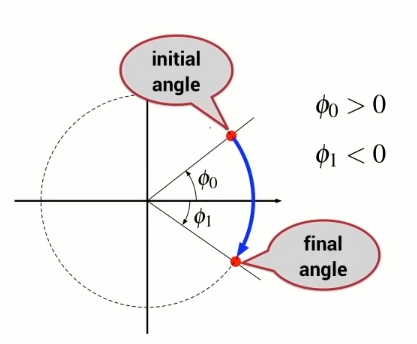

### Roll-Pitch-Yaw Interpolation

RPY angles can describe the orientation of a robot end-effector. If we have a starting orientation pose and a finishing pose, we can use **jtraj**(), to  interpolate between these poses using a quintic polynomial.

Conser interpolating between roll-pitch-yaw angles of (0, 0, 0) and (-π/2, π/2, π/4) radians over 100 time steps. 

Each of those points could be considered waypoints:

x = jtraj([0 0 0],           ... % Starting pose
          [-pi/2 pi/2 pi/4], ... % Ending pose
          100)

We can visualize the trajectory with plot:

plot(x); xlabel('time (s)'); ylabel('radians (r)'); title('RPY Trajectory'); grid on; legend('roll', 'pitch', 'yaw')

Another useful visualization would be animating the poses with **tranimate**.

To do this, we would have to map the corresponding orientation to a rotation matrix. 

We can do this for the entire trajectory using **rpy2r.** 

If we have *m *vectors of rpy values, rpy2tr will create *m rotation *matrices for each of those waypoints. However, the structure has form 3x3xm.

R = rpy2r(x);
size(R)

You can videw the mth matrix by calling:

R(:,:,1)        % 1st entry...
R(:,:,10)       % 10th entry...

Finally, we can animate the entire sequence using **tranimate** (call this in the command window).

clf;
tranimate(R, 'rgb', 'view', [45,45])

### Parabolic Blend Rotational Interpolation

So far jtraj has helped us generate multi-dimensional trajectories using quintic polynomials. Is it possible for us to use another function instead?

Yes, `mtraj()` is a similar multi-dimensional trajectory generator, but this function let's you **pass in another function** that can interpolate in a different way.

[Q,QD,QDD] = mtraj(
    @TFUNC,   ... % is not a variable but a scalar trajectory function that has to be passed with @ in front of the name of the function.
                  % @lspb or @tpoly are possible input functions
    Q0, ...       % is a (1xN) starting pose
    QF, ...       % is a (1xN) ending pose
    M             % is the number of steps.
    );

Consider starting with a starting and ending pose of RPY sequences and using @lspb over 50 time steps:

Q0 = [0, 0, 0];
QF = [pi/4, pi/2, pi/3];
[s, sd, sdd] = mtraj(@lspb, Q0, QF, 50)

Visualize the multi-dimensional lspb curves for position, velocity, and acceleration for the given rpy sequences:

subplot(3,1,1); plot(s);

 
q1 = 
 
1 < 0, 0, 0 >
 


subplot(3,1,2); plot(sd);
subplot(3,1,3); plot(sdd);

Notice we have the characteristic blends in position, trapezoids in velocity, and step discountinuities in accelerations. 

### Quaternion Interpolation

Earlier we saw the importance of quaternions. We also want to learn to generate paths and trajectories from quaternions as their interpolation leads to the shortest path between the points and with a uniform motion (see more [here](https://en.wikipedia.org/wiki/Slerp)). 

Start by creating a starting and ending pose as unit quaternions. The start pose can be the trivial pose:

q1 = UnitQuaternion

 
q2 = 
 
0.70711 < 0.70711, 0, 0 >
 


The ending pose can be a 90 degree rotation about the x-axis:

q2 = UnitQuaternion( rotx(pi/2))

 
ans = 
 
1 < 0, 0, 0 >
 


To interpolate quaternions using ***spherical linear interpolation (SLERP)***, we will make use of the `UnitQuaternion.interp()` method in the Quaternion class.

The way it is called starts by taking the starting pose quaternion, say q1, and then calling the method with the final pose quaternion as an input argument along with a 2nd argument [0-1] that indicates the state of the interpolation.

I.e. if the 0 is passed, the result is the initial quaternion:

q1.interp(q2,0)

 
ans = 
 
0.70711 < 0.70711, 0, 0 >
 


To get the final pose you can do:

q1.interp(q2,1)

 
ans = 
 
0.92388 < 0.38268, 0, 0 >
 


If you want the half-way point you can do:

q1.interp(q2,0.5)

s =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


We can also animate the quaternion trajectory.

To this end, we would have to create an interpolation vector *s *ranging from 0 to 1 in dt number of time steps:

s = [0:0.02:1]

 
x1 = 
 
                          
1 < 0, 0, 0 >             
0.99988 < 0.015707, 0, 0 >
0.99951 < 0.031411, 0, 0 >
0.99889 < 0.047106, 0, 0 >
0.99803 < 0.062791, 0, 0 >
0.99692 < 0.078459, 0, 0 >
0.99556 < 0.094108, 0, 0 >
0.99396 < 0.10973, 0, 0 > 
0.99211 < 0.12533, 0, 0 > 
0.99002 < 0.1409, 0, 0 >  
0.98769 < 0.15643, 0, 0 > 
0.98511 < 0.17193, 0, 0 > 
0.98229 < 0.18738, 0, 0 > 
0.97922 < 0.20279, 0, 0 > 
0.97592 < 0.21814, 0, 0 > 
0.97237 < 0.23345, 0, 0 > 
0.96858 < 0.24869, 0, 0 > 
0.96456 < 0.26387, 0, 0 > 
0.96029 < 0.27899, 0, 0 > 
0.95579 < 0.29404, 0, 0 > 
0.95106 < 0.30902, 0, 0 > 
0.94609 < 0.32392, 0, 0 > 
0.94088 < 0.33874, 0, 0 > 
0.93544 < 0.35347, 0, 0 > 
0.92978 < 0.36812, 0, 0 > 
0.92388 < 0.38268, 0, 0 > 
0.91775 < 0.39715, 0, 0 > 
0.9114 < 0.41151, 0, 0 >  
0.90483 < 0.42578, 0, 0 > 
0.89803 < 0.43994, 0, 0 > 
0.89101 < 0.45399, 0, 0 > 
0.88377 < 0.46793, 0, 0 > 
0.87631 < 0.48175, 0, 0 > 
0.86863 < 0.49546, 0, 0 > 
0.86074 < 0.50904, 0, 0 > 
0.85264 < 0.5225, 

x1 = q1.interp(q2,s)

Check the size and type of the output:

size(x1)

ans =      1    51


class(x1)

ans = 'UnitQuaternion'

Visualize by calling animate on the quaternion:

x1.animate('rgb','view', [45,45])

Note: an alternative way to animate might be as shown below:

We can now use **tranimate()**, though we must map the quaternion trajectory variable *x * to a rotation matrix first via the UnitQuaternion R method (best viewed in the command window). 

What should we expect? A simple 90 degree rotation about the x-axis. Look for it:

tranimate( x1.R, 'rgb', 'view', [45, 45])

s =          0
    0.0009
    0.0037
    0.0084
    0.0150
    0.0234
    0.0337
    0.0459
    0.0600
    0.0759


For an even smoother interpolation, we can use lspb or tpoly to create a smooth varying scalar `s``. `

s = lspb(0,1,50)

 
x2 = 
 
                          
1 < 0, 0, 0 >             
1 < 0.000736, 0, 0 >      
1 < 0.002944, 0, 0 >      
0.99998 < 0.006624, 0, 0 >
0.99993 < 0.011776, 0, 0 >
0.99983 < 0.018399, 0, 0 >
0.99965 < 0.026493, 0, 0 >
0.99935 < 0.036056, 0, 0 >
0.99889 < 0.047087, 0, 0 >
0.99822 < 0.059581, 0, 0 >
0.99729 < 0.073534, 0, 0 >
0.99604 < 0.088939, 0, 0 >
0.99439 < 0.10579, 0, 0 > 
0.99227 < 0.12406, 0, 0 > 
0.98961 < 0.14376, 0, 0 > 
0.98632 < 0.16485, 0, 0 > 
0.9823 < 0.1873, 0, 0 >   
0.97753 < 0.21079, 0, 0 > 
0.97218 < 0.23422, 0, 0 > 
0.96627 < 0.25753, 0, 0 > 
0.9598 < 0.28068, 0, 0 >  
0.95278 < 0.30368, 0, 0 > 
0.9452 < 0.32649, 0, 0 >  
0.93708 < 0.34912, 0, 0 > 
0.92841 < 0.37155, 0, 0 > 
0.91921 < 0.39376, 0, 0 > 
0.90948 < 0.41575, 0, 0 > 
0.89922 < 0.43749, 0, 0 > 
0.88845 < 0.45898, 0, 0 > 
0.87715 < 0.48021, 0, 0 > 
0.86536 < 0.50116, 0, 0 > 
0.85306 < 0.52182, 0, 0 > 
0.84027 < 0.54217, 0, 0 > 
0.82704 < 0.56215, 0, 0 > 
0.814 < 0.58087, 0, 0 >   
0.80141 < 0.59811,

And then leverage this smooth scalar in SLERP:

x2 = q1.interp(q2,s)

Animate:

x2.animate('rgb','view', [45,45])

T0 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


## Lec 04.7 (Ch 3.1) Cartesian Interpolation

We finally reach a point where we would like to interpolate not only rotation but also translation simultaneously. 

Doing both simultaneously is known as '**Cartesian Interpolation**'. 

We will still need a starting and ending pose. Mathematically, we cannot interpolate rotation matrices (or homogeneous transformation matrices) due to their orthonormal properties. Instead, interpolocation of orientation takes place as UnitQuaternions and translation vectors can be interpolated directly. 

The **ctraj()** method in the toolbox takes care of all of this and only asks for a starting and ending homogeneous transformation. 

Initial pose:

T0 = eye(4,4)

T1 =      0    -1     0     0
     1     0     0     5
     0     0     1     3
     0     0     0     1


Ending pose:

T1 = transl(0,5,3)*rpy2tr(0,0,pi/2)

Smooth trajectory between the two poses using the toolbox function ctraj() across 50 time-steps:

T = ctraj(T0, T1, 50);

ans =      4     4    50


size(T)

T(:,:,1)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T(:,:,50)

ans =     0.0000   -1.0000         0         0
    1.0000    0.0000         0    5.0000
         0         0    1.0000    3.0000
         0         0         0    1.0000


Finally, we can visualize it with tranimate (best seen in the command window):

tranimate(T, 'rgb', 'view', [45,4])